# Ángulo entre dos cargas

Durante este proyecto se está haciendo un análisis de las fuerzas que aplican entre dos cargas que cuelgan de un mismo punto. El objetivo es utilizar la función fzero para conseguir el valor del ángulo. 

m = 1.2; % kg
l = 0.25; % m
k = 9e+9; % Constante de Coulomb
g = 9.81; % m/s^2
E_0 = 8.85e-9; % Resistencia del vació
carga = 3e-5 ; % C

% Se evalua un aproximado a al ángulo de separación que se encuentra entre
% las cargas.
x0 = ((carga^2/(16*E_0*pi*l^2*m*g))^(1/3));

x0 = 0.1401

f = @(alpha) 16 * pi * E_0 * l^2 * (sin(alpha)^2) * m * g * tan(alpha) - carga^2 ; % Función de la fuerza
fprintf ("El ángulo en %f radianes\n es: ", x0); 

El ángulo en 0.140098 radianes
 es: 

[alpha, z0] = fzero(f, x0) % Función fzero para obtener alfa;

alpha = 0.1401

z0 = 2.0680e-25

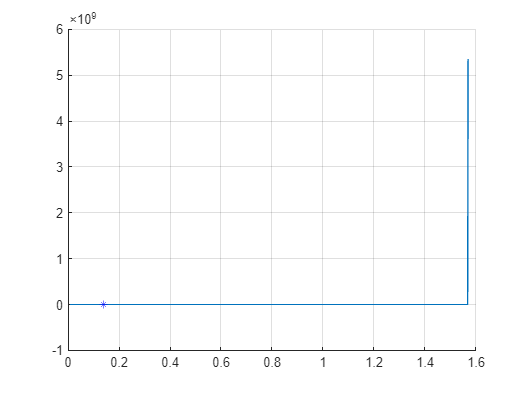


hold on

x = linspace (0.01, pi/2, 1000);
y = 16 * pi * E_0 * l.^2 .* (sin(x).^2) * m * g .* tan(x) - carga.^2;
plot(x,y); % graficación de alfa respecto a la fuerza-
plot(alpha, z0, "b", "Marker", "*")

grid on

hold off

## Informe y análisis de resultados

Como se puede ver por los resultados conseguidos, se puede encontrar que con los datos previstos, las cargas presentan un ángulo de 0.0302 radianes, que es aproximadamente 1.7294 grados. 

Esto lo podemos obtener analizando las fuerzas que ejercen a la carga en un sistema en equilibrio. Las fuerzas que aplican son la atracción de la gravedad, la fuerza de repulsión entre las cargas y la fuerza de tension ejercida por el cable que separa las cargas. Para conocer estos factores se utiliza una fórmula que determina la fuerza en el eje x mediante la ley de coulomb depspejada de forma que cruce el eje 0 cuando cuando el ángulo sea el indicado. Por ello es que utilizamos la función de fzero() para conseguir el ángulo. 